# **Video Processing: Laboratory 1:**

Adrià Garcia Coscolla: u232256

Ernest Fosch Muntané: u196572

### **Task 1.a:**

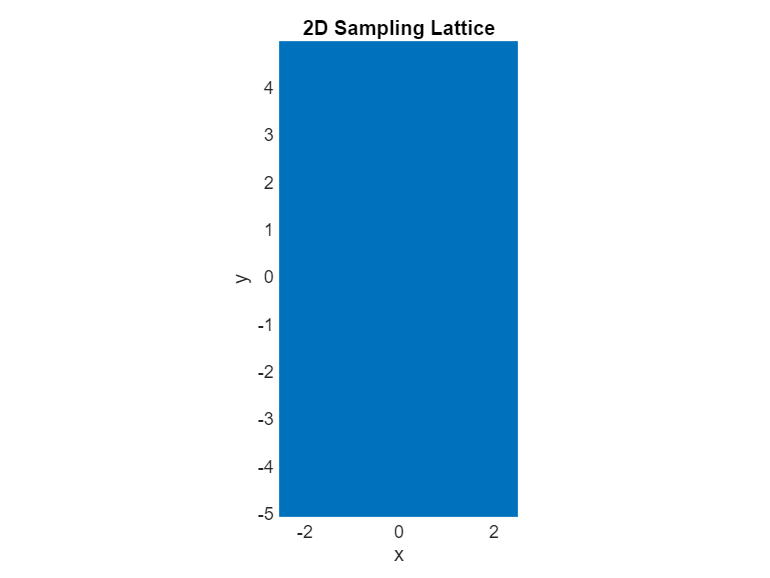

a=6;
b=2;
N=200; %We will have NxN samples if N is even or (N-1)x(N-1) if is odd.

[m,n]= meshgrid(-floor(N/2):floor(N/2)-1); %integer grid

psi= @(x,y)cos(2*pi*a*x) .* cos(2*pi*b*y) + ...
0.7*sin(pi*a*b*(x+y)) + ...
0.5*cos(pi*(a + 0.5*a*b)*x - pi*b*y); 

%sampling lattice:
V=[1/40,0;0,1/20];
% sampling grid, because V is diagonal:
x = V(1,1)*m;
y = V(2,2)*n;

psi_s = psi(x, y); %sampling of the function: psi_s = psi(Vn)

%2D plot of the sample lattice grid.
figure;
voronoi(x, y)
% plot(x,y, '.', 'MarkerSize', 20,'Color', 'b');
title('2D Sampling Lattice');
xlabel('x'); ylabel('y');
axis equal tight;
grid on;

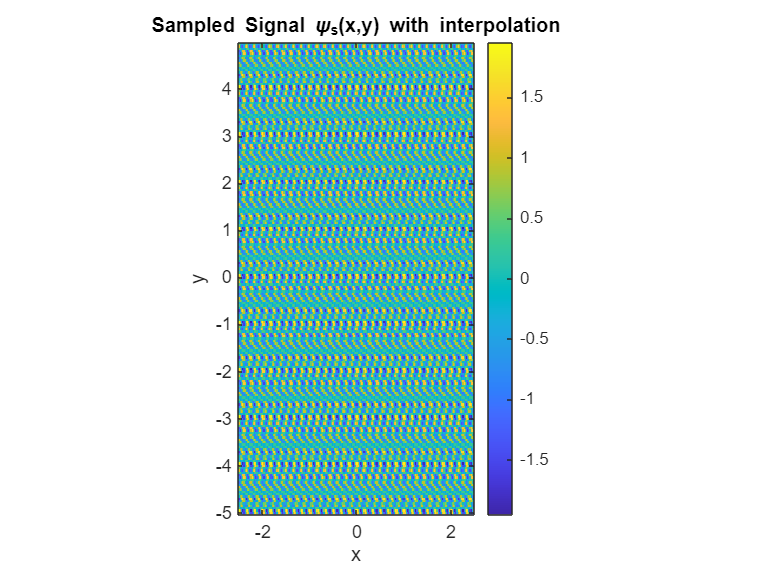


%2D plot of the sampled signal (psi_s)
figure;
imagesc(x(1,:), y(:,1), psi_s);
title('Sampled Signal \psi_s(x,y) with interpolation');
xlabel('x'); ylabel('y');
colorbar;
axis xy; %y pointing up
axis equal tight;

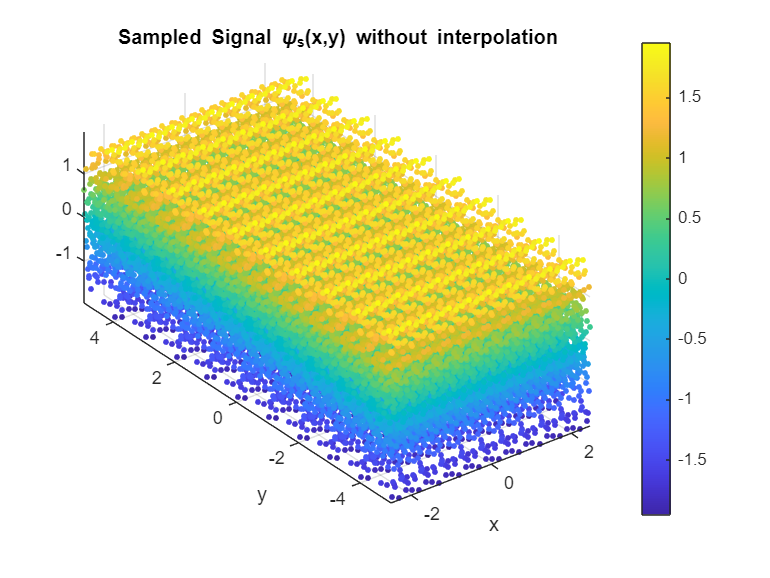

scatter3(x(:), y(:), psi_s(:), 10, psi_s(:), 'filled');
title('Sampled Signal \psi_s(x,y) without interpolation');
xlabel('x'); ylabel('y');
colorbar;
axis xy; %y pointing up
axis equal tight;

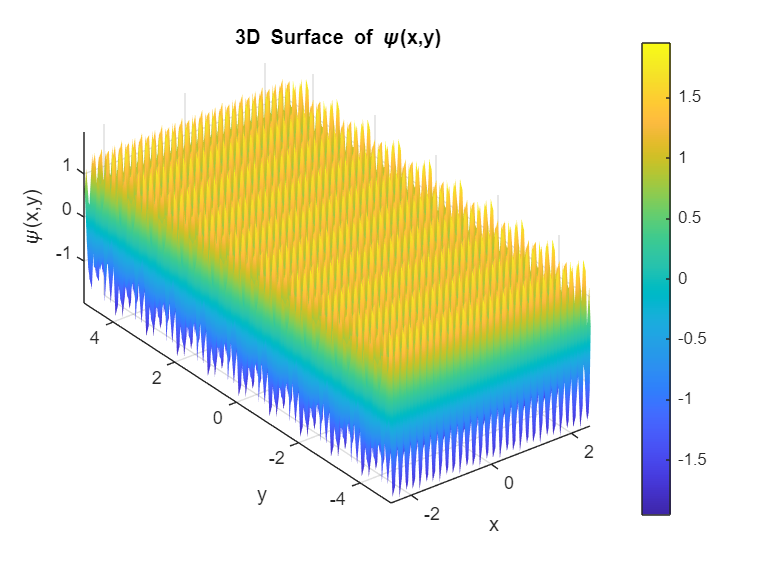



%3D plot of the sampled signal (psi_s)
figure;
surf(x, y, psi_s); % 3D surface
shading interp; % smooth shading
colorbar; % show color scale
axis equal;
xlabel('x'); ylabel('y'); zlabel('\psi(x,y)');
title('3D Surface of \psi(x,y)');


%Another way to create the sampling lattice grid:
%m = -floor(N/2)*V(1,1):V(1,1):(floor(N/2)-1)*V(1,1);
%n = -floor(N/2)*V(2,2):V(2,2):(floor(N/2)-1)*V(2,2);
%   [x,y]= meshgrid(m, n); %integer grid

**Task 1.b:**

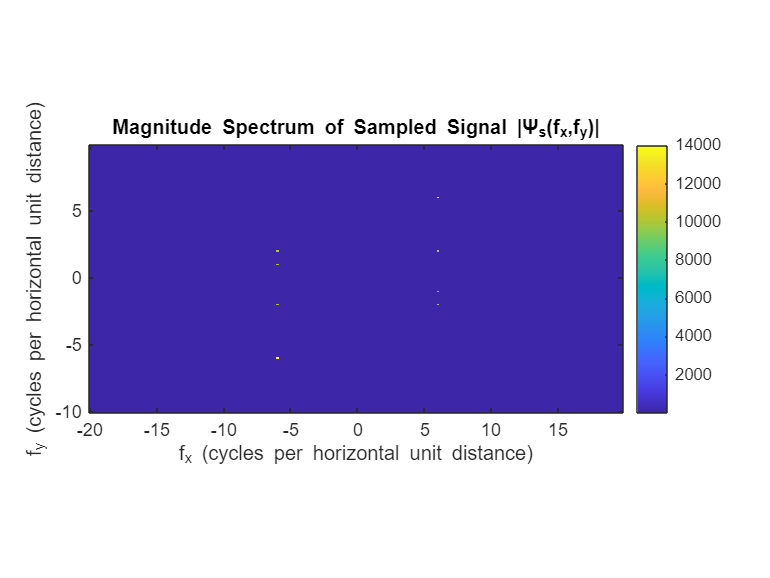

% 2D FFT of the sampled signal:
Psi = fftshift(fft2(psi_s)); % to center the frequency.

% Magnitude spectrum
Psi_mag = abs(Psi);

% log scale for better visibility
% Psi_log = log(1 + Psi_mag);

Nx = size(psi_s, 2);   % # columns
Ny = size(psi_s, 1);   % # rows

dx = V(1,1);   % 1/40: the increment on the x axis
dy = V(2,2);   % 1/20: the increment on the y axis

% x and y axes in frequency:
fx = (-Nx/2:Nx/2-1)/(Nx*dx);
fy = (-Ny/2:Ny/2-1)/(Ny*dy);

figure;
imagesc(fx, fy, Psi_mag);
axis xy;
axis equal tight;
colorbar;

xlabel('f_x (cycles per horizontal unit distance)');
ylabel('f_y (cycles per horizontal unit distance)');
title('Magnitude Spectrum of Sampled Signal |\Psi_s(f_x,f_y)|');

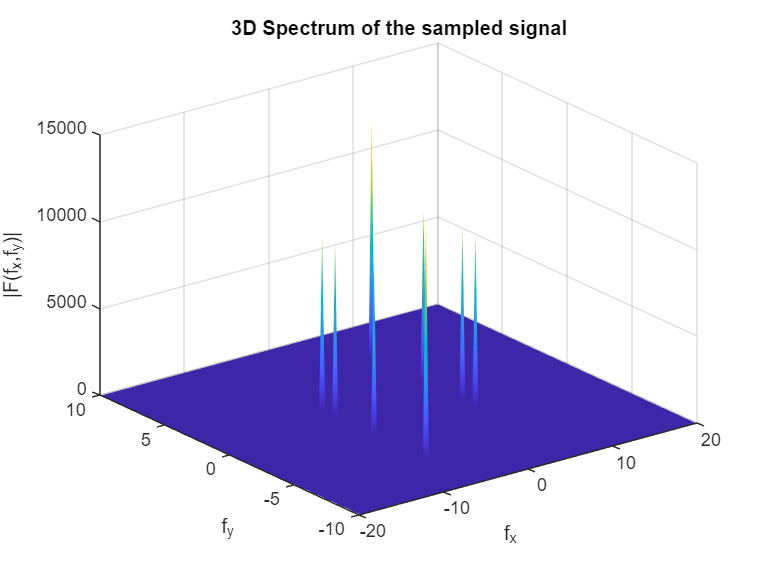


figure;
surf(fx, fy, Psi_mag);
shading interp;
xlabel('f_x'); ylabel('f_y'); zlabel('|F(f_x,f_y)|');
title('3D Spectrum of the sampled signal');

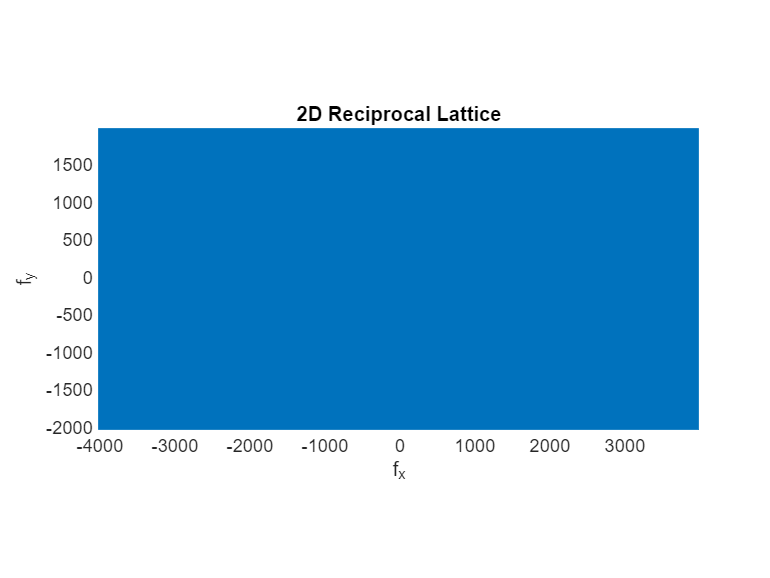

%reciprocal latice
U = inv(V');
m = -N/2*U(1,1):U(1,1):(N/2-1)*U(1,1);
n = -N/2*U(2,2):U(2,2):(N/2-1)*U(2,2);
[f_x,f_y]= meshgrid(m,n);

%2D plot of the reciprocal lattice grid.
figure;
voronoi(f_x,f_y)
%plot(f_x,f_y,'.', 'MarkerSize', 20,'Color', 'b')
title('2D Reciprocal Lattice');
xlabel('f_x'); ylabel('f_y');
axis equal tight;
grid on;

### **Task 2.a:**

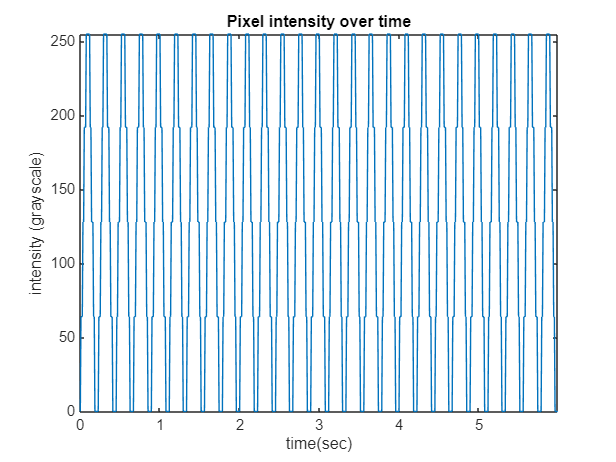

path = "\task2_orig120fps.avi";
vid = VideoReader(path);

c = 20;
d = 30;

%Coords of the pixel:
x = 5*c; 
y = 5*d;

n_frames = vid.NumFrames; %# of frames = diff values of the pixel

pixel_values = zeros(1,n_frames); %array to store the grayscale values of the pixel.
i = 1;
while hasFrame(vid)
    frame = readFrame(vid,'native');
    pixel_values(i) = double(frame.cdata(y,x)); % y: eix vertical (files), x:eix horitzontal (columnes)
    i = i+1;
end

fr = vid.FrameRate; %frame rate = 120 frames/s
time = (0:n_frames-1) / fr;

figure;
plot(time, pixel_values)
xlabel('time(sec)'); ylabel('intensity (grayscale)');
title('Pixel intensity over time');
axis tight;

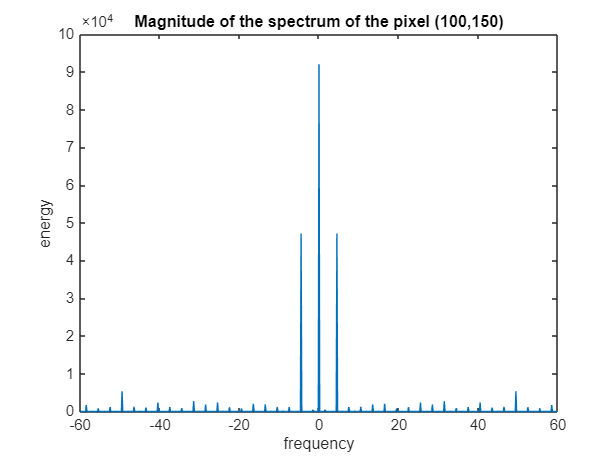


%From the plot above we can recover the period of the intesity of the pixel
%that is 0.45-0.225 = 0.225s. Therefore, the fundamental frequency is
%1/0.225 = 4.44Hz

F_pixel = fftshift(fft(pixel_values)); %FFT centered at 0
F_mag = abs(F_pixel); %We take the magnitude

f = (-n_frames/2:n_frames/2-1)*(fr/n_frames); %frequency axis

figure;
plot(f, F_mag)
xlabel('frequency'); ylabel('energy');
title("Magnitude of the spectrum of the pixel (" + x + "," + y + ")");

clear vid;
%We ignore the peak at frequency 0. The peak we obtain is at 4.5Hz, which
%corresponds to the fundamental frequency we have previously found.
%Therefore, the minimum sampling frequency would be fs>2*4.5 = 9Hz.

### **Task 2.c:**

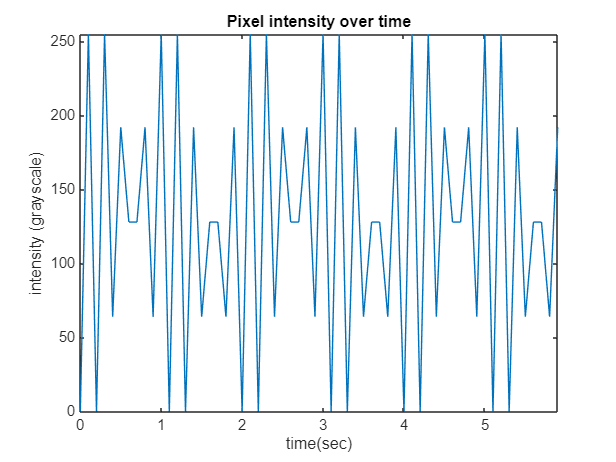

vid_120 = VideoReader(path); %We read the 120fps video

vid_10 = VideoWriter("task2_sampled_10Hz.avi"); %We create a new video.
vid_10.FrameRate = 10; %We choose 10 to be our frame rate.
open(vid_10);

frame_idx = 0;
step = vid_120.FrameRate/vid_10.FrameRate; %We will keep the frames every 12 frames.
n_frames = vid_120.NumFrames/step; %The total number of frames the video will have.
pix_val = zeros(1,n_frames); %array to store the values that our pixel will have in the new video.

i = 1;

while hasFrame(vid_120)
    frame = readFrame(vid_120, 'native');
    if mod(frame_idx, step) == 0 %"sample" every 12 frames.
        writeVideo(vid_10, frame.cdata);
        pix_val(i) = double(frame.cdata(y,x));
        i = i + 1; 
    end

    frame_idx = frame_idx + 1;
end

close(vid_10);
clear vid_120;

fr = vid_10.FrameRate; %frame rate = 10 frames/s
time = (0:size(pix_val,2)-1) / fr;

figure;
plot(time, pix_val)
xlabel('time(sec)'); ylabel('intensity (grayscale)');
title('Pixel intensity over time');
axis tight;

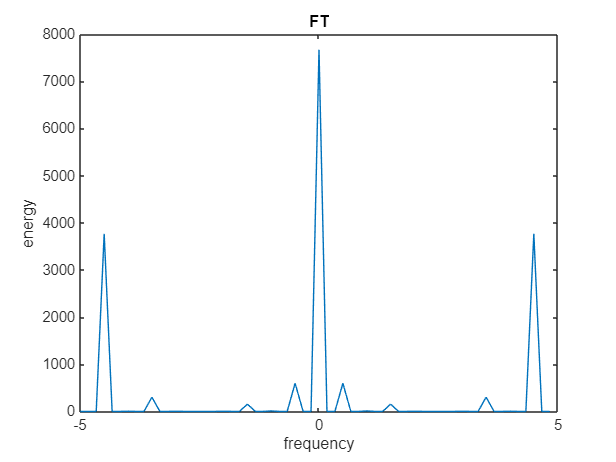


F_pixel = fftshift(fft(pix_val));
% Magnitude spectrum
F_mag = abs(F_pixel);

f = (-size(pix_val,2)/2:size(pix_val,2)/2-1)*(fr/size(pix_val,2)); %frequency axis

figure;
plot(f, F_mag)
xlabel('frequency'); ylabel('energy');
title('Spectrum of the pixel at 10fps');

### **Task 2.d**

vid  = VideoReader(path);

fr = vid.FrameRate; % frame rate 120 fps
N  = vid.NumFrames;
H  = vid.Height; %num of pixels
W  = vid.Width; %num of pixels

video = zeros(H, W, N); %This matrix will contain the values of each pixel at every frame. This is just video(y,x,t)

i = 1;
while hasFrame(vid)
    frame = readFrame(vid,'native');
    video(:,:,i) = double(frame.cdata); % we copy each frame
    i = i + 1;
end

F = fft(video, [], 3); % This computes the FFT for each pixel across all frames, the 3rd dimension (as we did before for 1 pixel)

% Frequency axis
f = (0:N-1) * fr / N; % we have N frequency bins
half = 1:floor(N/2); % we just need half of the spectrum (it's symmetric)

Fmag = abs(F(:,:,half)); % We compute the magnitude spectrum (only for the positive frequencies)
f_half = f(half); %we get the frequency bins from 0 to N/2-1

Fmag(:,:,1) = 0; % we ge rid of the frequency 0

%% Dominant (fundamental) frequency per pixel
[~, idx] = max(Fmag, [], 3); % We find the highest frequency peak of each pixel. This returns the max value (energy) and the index (frequency)
f0s = f_half(idx);

f0_max = max(f0s(:)); % We find the maxium frequency of among all pixels.

fs_min = 2 * f0_max; % Following Nyquist we determine the new minimum sampling frequency

fprintf('The maximum fundamental frequency in the video is: %.2f Hz\n', f0_max);

The maximum fundamental frequency in the video is: 20.33 Hz


fprintf('The minimum sampling frequency to avoid aliasing is: %.2f Hz\n', fs_min);

The minimum sampling frequency to avoid aliasing is: 40.67 Hz


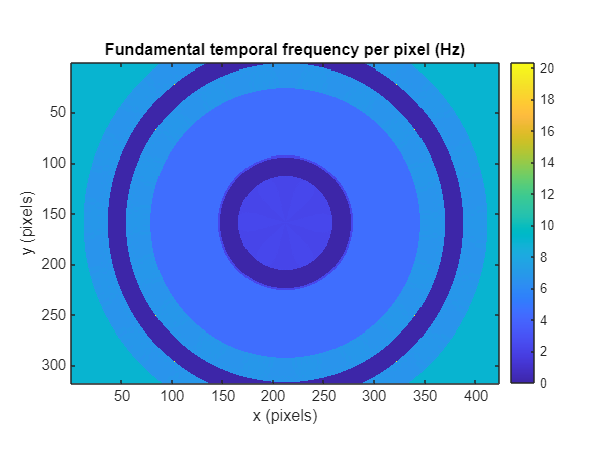


figure;
imagesc(f0_map);
colorbar;
xlabel('x (pixels)');
ylabel('y (pixels)');
title('Fundamental temporal frequency per pixel (Hz)');
axis image;

% We create a new video that has a lower frame rate, but above the
% minimum to avoid aliasing.
vid_120 = VideoReader(path);
vid_60 = VideoWriter("task2_sampled_60Hz.avi");
vid_60.FrameRate = 60;
open(vid_60);

step = vid_120.FrameRate/vid_60.FrameRate;
n_frames = vid_120.NumFrames/step;
pix_val = zeros(1,n_frames);

frame_idx = 0;
i = 1;

while hasFrame(vid_120)
    frame = readFrame(vid_120, 'native');
    if mod(frame_idx, step) == 0 %"sample" every 12 frames.
        writeVideo(vid_60, frame.cdata);
        pix_val(i) = double(frame.cdata(y,x));
        i = i + 1; 
    end

    frame_idx = frame_idx + 1;
end

close(vid_60);


vid_120 = VideoReader(path);
vid_20 = VideoWriter("task2_sampled_20Hz.avi");
vid_20.FrameRate = 20;
open(vid_20);

step = vid_120.FrameRate/vid_20.FrameRate;
n_frames = vid_120.NumFrames/step;
pix_val = zeros(1,n_frames);

frame_idx = 0;
i = 1;

while hasFrame(vid_120)
    frame = readFrame(vid_120, 'native');
    
    if mod(frame_idx, step) == 0
        writeVideo(vid_20, frame.cdata);
        pix_val(i) = double(frame.cdata(y,x));
        i = i + 1; 
    end
    
    frame_idx = frame_idx + 1;
end

close(vid_20);